**FILTRADO AMPLIFICADOR**

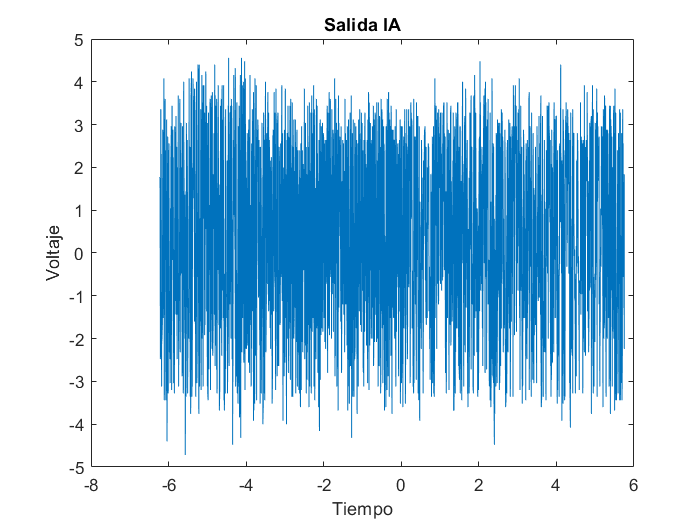

%Ruta del archivo
ruta_ampli = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Matlab\ampli.csv';

%Guardamos los datos
datos_ampli = csvread(ruta_ampli);

%Extraemos las columnas
base_tiempos = datos_ampli(:, 1);
voltaje = datos_ampli(:, 2);

%Representamos los datos guardados
plot(base_tiempos, voltaje);
xlabel('Tiempo');
ylabel('Voltaje');
title('Salida IA');

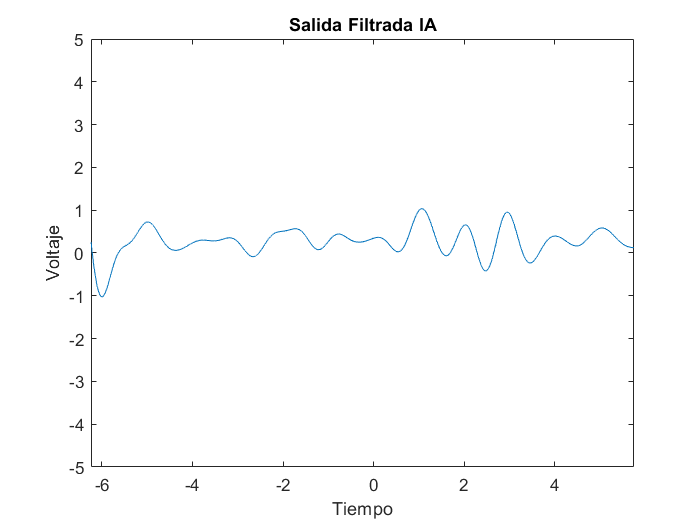


%Procedemos al filtrado de la señal con un IIR
fs = 500;
f_corte = 4;
orden_filtro = 4;
filtro = designfilt('lowpassiir', 'FilterOrder', orden_filtro, 'PassbandFrequency', f_corte, 'SampleRate', fs);
voltaje_filtrado = filtfilt(filtro, voltaje);

%Representamos la señal filtrada
plot(base_tiempos, voltaje_filtrado);
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-6.24 5.75]);
ylim([-5 5]);
title('Salida Filtrada IA');

**FILTRADO MULTIPLICADOR**

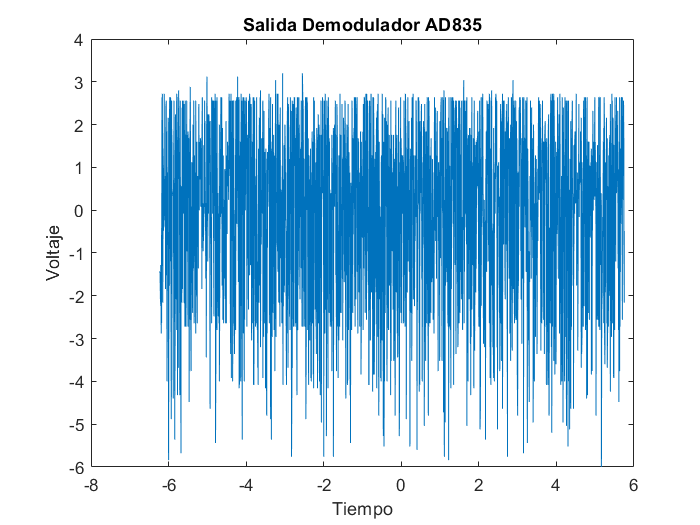

% Ruta del archivo
ruta_multi = 'D:\Master\Segundo Cuatrimestre\Trabajo Fin de Master\TFM presion arterial\Matlab\multi.csv';

%Guardamos los datos
datos_multi = csvread(ruta_multi);

%Extraemos las columnas
base_tiempos = datos_multi(:, 1);
voltaje = datos_multi(:, 2);

%Representamos los datos guardados
plot(base_tiempos, voltaje);
xlabel('Tiempo');
ylabel('Voltaje');
title('Salida Demodulador AD835');

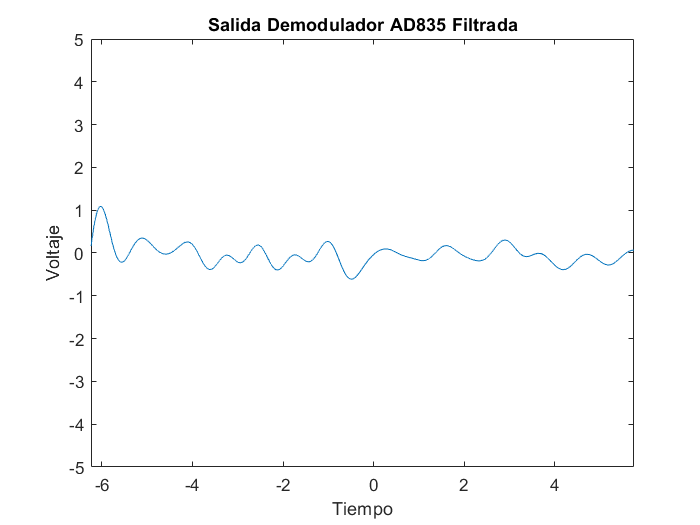


%Procedemos al filtrado de la señal con un IIR
fs = 500;
f_corte = 4;
orden_filtro = 4;
filtro = designfilt('lowpassiir', 'FilterOrder', orden_filtro, 'PassbandFrequency', f_corte, 'SampleRate', fs);
voltaje_filtrado = filtfilt(filtro, voltaje);

%Representamos la señal filtrada
plot(base_tiempos, voltaje_filtrado);
xlabel('Tiempo');
ylabel('Voltaje');
xlim([-6.24 5.75]);
ylim([-5 5]);
title('Salida Demodulador AD835 Filtrada');